
clc; clear; close all;


files = {'caso5.csv', 'caso6.csv', 'caso7.csv', 'caso8.csv'};
legends = {'Caso 5', 'Caso 6', 'Caso 7', 'Caso 8'};


line_colors = {[0 0.4470 0.7410], [0.8500 0.3250 0.0980], ...
               [0.4660 0.6740 0.1880], [0.4940 0.1840 0.5560]}; 

ref_h1 = 1.5;      
V_eq = 4.5113;     
t_limit = 800;     
buffer = 50; 

datos = struct();
fprintf('--- ANÁLISIS MATEMÁTICO TANQUE 1 (0 a %d s) ---\n', t_limit);

--- ANÁLISIS MATEMÁTICO TANQUE 1 (0 a 800 s) ---




for i = 1:length(files)
    try
        raw = readmatrix(files{i}, 'Delimiter', ';', 'DecimalSeparator', ',');
        t_raw = (raw(:,2) - raw(2,2)) / 1000; 
        
   
        idx_start = find(raw(:,6) > 0.05, 1, 'first'); 
        if isempty(idx_start), idx_start = 1; end 
        idx_s = max(1, idx_start - buffer);
        
        t_all = t_raw(idx_s:end) - t_raw(idx_s);
        u_all = raw(idx_s:end, 5);      % Voltaje
        h1_n_all = raw(idx_s:end, 3);    % L1 con Ruido (Columna 3)
        h1_c_all = raw(idx_s:end, 6);    % L1 Limpio (Columna 6)
        
     
        mask = (t_all <= t_limit);
        t = t_all(mask);
        u = u_all(mask);
        h1_n = h1_n_all(mask);
        h1_c = h1_c_all(mask);
       
        dt = mean(diff(t));             
        error = abs(ref_h1 - h1_c);     
        
        IAE = sum(error) * dt;          
        ITAE = sum(t .* error) * dt;    
        
        datos(i).t = t;
        datos(i).u = u;
        datos(i).h1_n = h1_n;
        datos(i).h1_c = h1_c;
        datos(i).IAE = IAE;
        datos(i).ITAE = ITAE;

        fprintf('%s -> IAE: %.2f | ITAE: %.2f\n', legends{i}, IAE, ITAE);
    catch
        fprintf('Error en archivo: %s\n', files{i});
    end
end

Caso 5 -> IAE: 70.18 | ITAE: 2624.44
Caso 6 -> IAE: 68.99 | ITAE: 2525.12
Caso 7 -> IAE: 69.82 | ITAE: 2693.41
Caso 8 -> IAE: 72.66 | ITAE: 2974.59


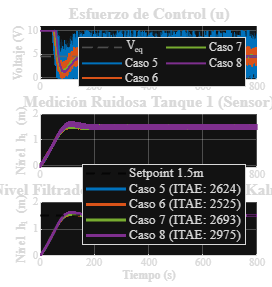



hFig = figure('Color', 'w', 'Position', [100 50 900 950]);
tlo = tiledlayout(3, 1, 'Padding', 'compact', 'TileSpacing', 'tight');


nexttile; hold on;
yline(V_eq, '--', 'Color', [0.4 0.4 0.4], 'LineWidth', 1.2, 'DisplayName', 'V_{eq}');
for i = 1:length(datos)
    plot(datos(i).t, datos(i).u, 'Color', line_colors{i}, 'LineWidth', 1.5, 'DisplayName', legends{i});
end
ylabel('Voltaje (V)', 'FontWeight', 'bold'); title('Esfuerzo de Control (u)', 'FontSize', 12);
grid on; xlim([0 t_limit]); ylim([-0.5 11]);
legend('Location', 'northeast', 'NumColumns', 2, 'FontSize', 9);


nexttile; hold on;
for i = 1:length(datos)
    c = line_colors{i};
    plot(datos(i).t, datos(i).h1_n, 'Color', [c 0.3], 'LineWidth', 0.5);
end
ylabel('Nivel h_1 (m)', 'FontWeight', 'bold'); title('Medición Ruidosa Tanque 1 (Sensor)', 'FontSize', 12);
grid on; xlim([0 t_limit]);


nexttile; hold on;
yline(ref_h1, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Setpoint 1.5m');
for i = 1:length(datos)
    plot(datos(i).t, datos(i).h1_c, 'Color', line_colors{i}, 'LineWidth', 2.2, ...
        'DisplayName', sprintf('%s (ITAE: %.0f)', legends{i}, datos(i).ITAE));
end
ylabel('Nivel h_1 (m)', 'FontWeight', 'bold'); xlabel('Tiempo (s)', 'FontWeight', 'bold');
title('Nivel Filtrado Tanque 1 (Estimación Kalman)', 'FontSize', 12);
grid on; xlim([0 t_limit]);
legend('Location', 'southeast', 'FontSize', 10);

set(findall(gcf,'-property','FontName'),'FontName','Times New Roman');